## DACS Introduction to Bioinformatics 2024

# Sequence alignment 

RING1 (Really Interesting New Gene 1 - yes it really is called that!) is a protein which is involved in lots of complexes (where proteins join together to perform a function) and is involved in regulating the expression of other genes.  The strongest known disease association is with asthma, where 9 different studies have associated 7 different positions in the gene with increased chance of asthma when these positions are mutated.  We are going to compare the sequence of this protein between humans and groundhogs.

- As we want the peptide sequence and not the nucleotide sequence we use the command **getgenpept** to load data from the online database genbank using the accession code. Load the peptide sequences from both species. (Human RING1 accession number NP_002922; Groundhog accession number KAI6059420).

sequenceRing = getgenpept('NP_002922','SequenceOnly',true)

sequenceRing = 'MTTPANAQNASKTWELSLYELHRTPQEAIMDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAPDSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAPSPPEPGGEIELVFRPHPLLVEKGEYCQTRYVKTTGNATVDHLSKYLALRIALERRQQQEAGEPGGPGGGASDTGGPDGCGGEGGGAGGGDGPEEPALPSLEGVSEKQYTIYIAPGGGAFTTLNGSLTLELVNEKFWKVSRPLELCYAPTKDPK'

sequenceK = getgenpept('KAI6059420','SequenceOnly',true)

sequenceK = 'MTTPANAQNASKTWELSLYELHRTPQEAIMDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPMPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAPDSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAPSPPEPGGEIELVFRPHPLLVEKGEYCQTRYVKTTGNATVDHLSKYLALRIALERRQQQEAGEPGGPGGGASDTGGPDGGGGEGGGTGGGDGPEEPALPSLEGVSEKQYTIYIAPGGGAFTTLNGSLTLELVNEKFWKVSRPLELCYAPTKDPK'

        2. Use the **seqdotplot** command on these two sequences, label the plot and explain what it shows.

                a.Based on this plot, should you perform local or global alignment with these sequences? Why?

                Answer: **Local** **alignment** is more appropriate for these sequences because the plot shows several isolated clusters of high similarity, represented by denser, darker areas. These clusters suggest that only certain parts of the sequences are similar, while other regions show low similarity. A global alignment would force alignment across the entire sequences, introducing excessive gaps and mismatches in regions with low similarity. Local alignment, on the other hand, will focus on the high-similarity regions, providing a more meaningful and accurate alignment by aligning only the most similar subsequences.

seqdotplot(sequenceRing,sequenceK)

        3. Global alignment can be performed using **nwalign **and local alignment using **swalign**. Use the type of alignment determined in question 2. Use the option **Showscore **to display the results**. **Each function can give 2 outputs, make sure to store them both (the score and the alignment).  

    -I will do both alignemnts to check them both out 

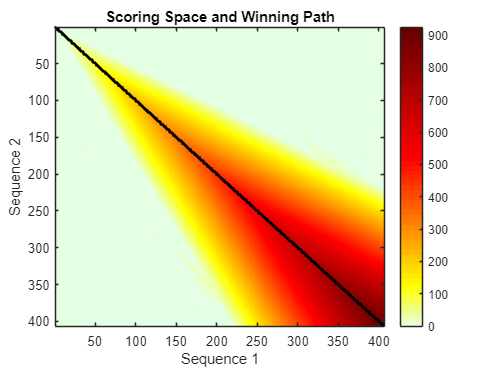

localalignemnt1 = 924

localalignemnt1 = swalign(sequenceRing,sequenceK,'Showscore',true)

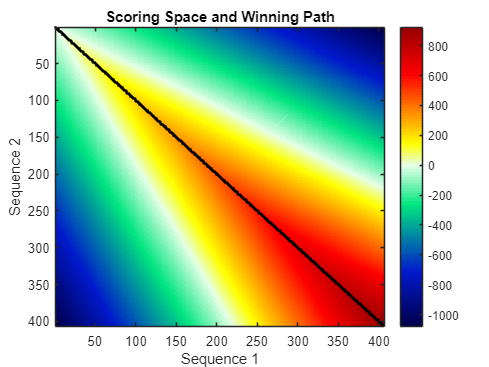

globalalignment1 = 924

globalalignment1 = nwalign(sequenceRing,sequenceK,'Showscore',true)

        a) What do the results show?

        -The results show that both local and global alignments achieved the same optimal score of 924, indicating strong similarity between key regions in the sequences

        b) What does the plot produced mean?

-The plot shows the alignment scoring space, with color intensity indicating scores. In **local alignment**, high scores are clustered around specific regions, emphasizing high-similarity segments. In **global alignment**, the gradient covers the entire matrix, showing an end-to-end alignment that includes penalties for low-similarity regions. This highlights the different focuses: local alignment on matching subsequences, global alignment on the full sequence.

        c) Find out what the scoring matrices and the gap penalties are by default.  What do these parameters mean and why they are important?    

        4. To assess the significance of the scores obtained for our alignment we need to compare the scores to that of random sequences which have the same properties as the real sequence.  We will do this two ways; 

            a) Firstly with **randperm**.  Use this function to permute the data for the one of the sequences many times and generate the alignment scores of these permuted sequences to the original for the other.  Plot these sequences into a histogram and show the real data on this plot as well.  Is it significant?

% Number of permutations
num_permutations = 1000;

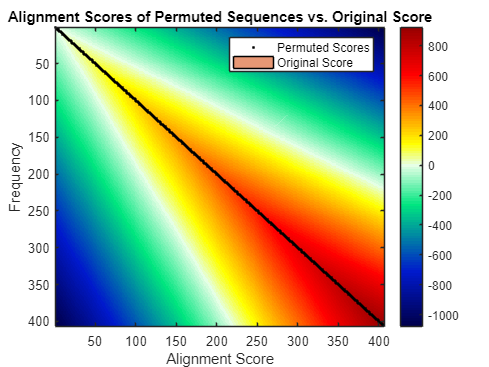

perm_scores = zeros(1, num_permutations);

% Perform random permutations and align
for i = 1:num_permutations
    % Randomly permute the groundhog sequence
    permuted_sequence = sequenceK(randperm(length(sequenceK)));
    
    % Perform local alignment with the permuted sequence
    [score, ~] = swalign(sequenceRing, permuted_sequence);
    perm_scores(i) = score;
end

% Plot the histogram of permuted scores
histogram(perm_scores, 'Normalization', 'probability');
hold on;

% Plot the original alignment score as a vertical line
original_score = 924; % Use the previously calculated score from your alignment
xline(original_score, 'r', 'LineWidth', 2, 'Label', 'Original Score');

title('Alignment Scores of Permuted Sequences vs. Original Score');
xlabel('Alignment Score');
ylabel('Frequency');
legend('Permuted Scores', 'Original Score');
hold off;


% Check significance by comparing original score to permutation scores
p_value = sum(perm_scores >= original_score) / num_permutations;
fprintf('p-value: %.4f\n', p_value);

p-value: 0.0000


            b) Secondly, let’s generate random sequences with the same features as our original sequence. Use **aacount** to count the number of times each amino acid occurs in the shorter sequence.  Now use **randseq **with the **FromStructure** option to generate sequences based on that distribution.  Make another histogram, is the real data significant?

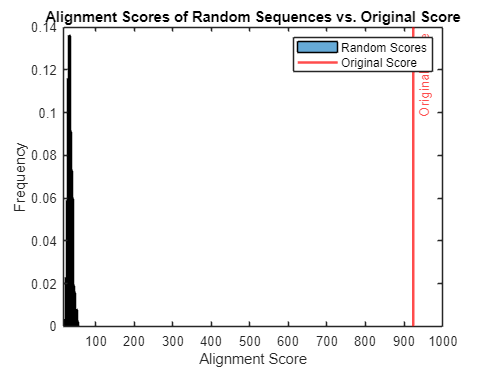

% Get amino acid composition of the groundhog sequence
aa_composition = aacount(sequenceK);

% Define the structure for random sequence generation
seq_structure = struct();
amino_acids = fieldnames(aa_composition);
for i = 1:length(amino_acids)
    seq_structure.(amino_acids{i}) = aa_composition.(amino_acids{i});
end

% Generate random sequences based on the composition and align
num_random_sequences = 1000;
random_scores = zeros(1, num_random_sequences);

for i = 1:num_random_sequences
    % Generate a random sequence with the same amino acid composition
    random_sequence = randseq(length(sequenceK), 'FromStructure', seq_structure);
    
    % Perform local alignment with the random sequence
    [score, ~] = swalign(sequenceRing, random_sequence);
    random_scores(i) = score;
end

% Plot the histogram of scores for random sequences
histogram(random_scores, 'Normalization', 'probability');
hold on;

% Plot the original alignment score as a vertical line
xline(original_score, 'r', 'LineWidth', 2, 'Label', 'Original Score');

title('Alignment Scores of Random Sequences vs. Original Score');
xlabel('Alignment Score');
ylabel('Frequency');
legend('Random Scores', 'Original Score');
hold off;


% Check significance by comparing original score to random scores
p_value_random = sum(random_scores >= original_score) / num_random_sequences;
fprintf('p-value (random composition): %.4f\n', p_value_random);

p-value (random composition): 0.0000


## Assignment: 

The white-rumped munia is an Indian bird which also has a RING1 protein.  The accession number of this protein sequence is [XP_021403354](https://www.ncbi.nlm.nih.gov/protein/XP_021403354.1). How close is this to the human protein?  Explain your results.

Make a new livescript with your working and explanations for this part and submit this file to the assignment on canvas. 

sequenceRing = getgenpept('NP_002922','SequenceOnly',true)

sequenceRing = 'MTTPANAQNASKTWELSLYELHRTPQEAIMDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAPDSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAPSPPEPGGEIELVFRPHPLLVEKGEYCQTRYVKTTGNATVDHLSKYLALRIALERRQQQEAGEPGGPGGGASDTGGPDGCGGEGGGAGGGDGPEEPALPSLEGVSEKQYTIYIAPGGGAFTTLNGSLTLELVNEKFWKVSRPLELCYAPTKDPK'

sequenceBird = getgenpept('XP_021403354','SequenceOnly',true)

sequenceBird = 'MAAPAGAQSASKTWELSLYELHRTPQEAIMDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSRDEYEAHQDRVLAKLSRLHNQQALSSSIEEGLKMQAMHRFGFWAGFGDIFGVILGIFLGWFWAVFGVLTPVFPQPLNGSLTLELVNEKFWKLSKPLELFYAPSKEQK'

## **Dot-Matrix Visualization**

A dot matrix is a powerful visual tool in bioinformatics used to compare two sequences. By plotting their similarities on a grid, it highlights regions of alignment, revealing conserved sequences and potential matches. This approach provides an intuitive first look at the degree of similarity between the sequences, with dots indicating matching segments.

lengthRing=length(sequenceRing)

lengthRing = 406

lengthBird = 220

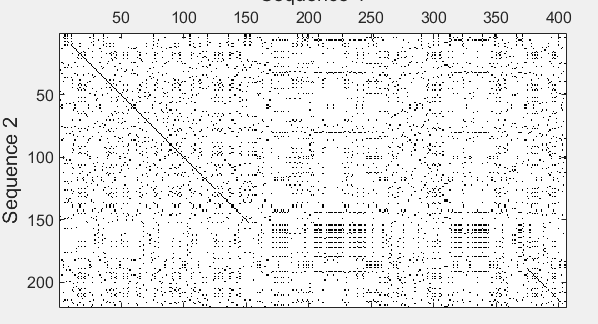


lengthBird = length(sequenceBird)

Matches = 5358


Matches=seqdotplot(sequenceRing,sequenceBird)

## **Detailed Analysis:**

The dot matrix plot suggests that **local alignment** is the optimal choice for comparing these sequences, and here’s why:

### **1. ****Sequence Length Disparity**

The sequences have noticeably different lengths, making global alignment less effective. In global alignment, the entire length of both sequences would be aligned, forcing gaps and misalignments to match the longer sequence (e.g., the human sequence). This would result in excessive penalties, reducing the overall alignment score and obscuring meaningful biological insights.

### **2. ****Identified Region of High Similarity**

A clear diagonal region of similarity is observed from approximately coordinates (0, 0) to (150, 150). This pattern indicates a segment where the sequences are closely related, suggesting a conserved region, such as a functional domain or a shared motif. This high-density region of matches implies that the sequences share a local feature of biological significance.

**3. ****Scattered Matches Beyond the Core Region**

Outside the main alignment region, the dot matrix shows only sporadic matches, indicating that the sequences do not align well in their entirety. These scattered points may represent random or coincidental similarities rather than true homology. Thus, attempting a global alignment would dilute the meaningful local alignments with noise from unrelated segments.

**4. ****Biological Interpretation**

The concentrated region of similarity suggests that the sequences might share a specific functional domain or a conserved motif, possibly related to a particular biological process or structural feature. This could be an indication of evolutionary conservation, even if the rest of the sequences have diverged significantly.

**5. ****Optimal Strategy: Local Alignment**

Given the localized nature of the similarity, a local alignment algorithm (e.g., Smith-Waterman) would focus on aligning the most similar regions while ignoring unrelated sections. This approach preserves the biological relevance of the conserved segment without being penalized by mismatches or gaps in the non-aligning parts of the sequences.

In summary, the dot matrix analysis highlights a strong localized similarity, making local alignment the most appropriate choice for revealing biologically meaningful relationships in these sequences.

## Alignment

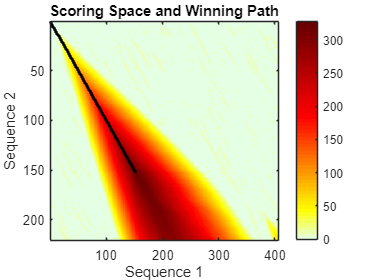

localalignemnt = 327

localalignemnt = swalign(sequenceRing,sequenceBird,'Showscore',true)

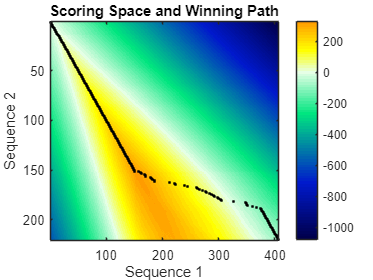

globalalignment = -59.6667

globalalignment = nwalign(sequenceRing,sequenceBird,'Showscore',true)

**Analysis:**

In this comparison, I applied both local and global alignment methods to evaluate sequence similarity and justify the chosen approach. The results show a clear preference for local alignment, as seen in the scoring and visual representation:

**1. ****Comparison of Alignment Scores**

- **Local Alignment Score:** The score for local alignment is **327**, which is significantly higher than the global alignment score of **-59.67**. This difference suggests a strong match within a specific region of the sequences (around coordinates (0, 0) to (150, 150)). Local alignment focuses on aligning the most similar subsequences, highlighting conserved regions without penalizing non-matching segments.

- **Global Alignment Score:** The global alignment score of **-59.67** is low, as expected. This is due to the algorithm’s attempt to align the entire length of both sequences, introducing many gaps and mismatches because of differences in sequence length and non-conserved regions.

**2. ****Visualization of Local Alignment**

- The plot of the local alignment shows a heatmap of the alignment scoring matrix. High-scoring regions are marked in red, indicating strong matches. The best alignment path, represented by a black line, corresponds to the most similar subsequence (from (0, 0) to (150, 150)). This confirms the presence of a conserved segment, reflected in the high score of **327**.

- An interesting feature is a small yellow spike in the bottom-right corner of the plot. This corresponds to a diagonal line in the dot matrix, indicating another area of local similarity that was captured by the alignment algorithm.

**3. ****Visualization of Global Alignment**

- The global alignment plot exhibits a different pattern, with blue and yellow regions indicating negative scores from mismatches and gaps. The alignment path spans across the entire length of the sequences, attempting to align them from start to finish, which results in a lower overall score due to the many gaps introduced.

**4. ****Scoring Matrix and Gap Penalty**

- The alignment was performed using the **BLOSUM50** scoring matrix by default. This matrix is designed for sequences with around 50% similarity or less, and each entry represents the substitution score for amino acids. It prioritizes biologically meaningful alignments based on observed evolutionary changes.

- A gap opening penalty of **8** was applied, which ensures that gaps are introduced only when they provide a significant improvement to the alignment. This helps maintain biological relevance in the aligned sequences.

**5. ****Exploring Alternative Scoring Functions**

- Next, I plan to experiment with different scoring matrices and gap penalties to assess their impact on the alignment results, particularly on the winning path. By adjusting these hyperparameters, I can better understand the sensitivity of the local alignment and whether different settings yield more accurate or biologically meaningful alignments.

In summary, the clear region of similarity captured by local alignment and the higher score of **327** underscore its effectiveness for these sequences, while global alignment struggles due to the length disparity and non-conserved segments. Exploring alternative parameters will provide further insights into the robustness of these findings.

## Change of parameters

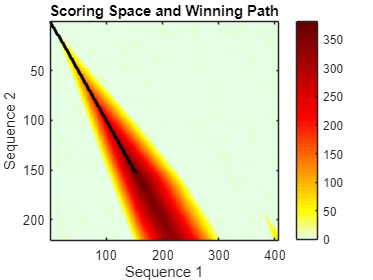

localAlignment = swalign(sequenceRing, sequenceBird, 'ScoringMatrix', 'BLOSUM62','GapOpen', 10,'Showscore', true);

**Explanation:**

In this heatmap, I performed local alignment again, but this time using the **BLOSUM62** scoring matrix instead of **BLOSUM50**. BLOSUM62 is more sensitive to detecting similarities between closely related sequences and rewards conservative substitutions more generously. This change led to an increase in the alignment score from **327** to **381**, indicating a stronger match.

Looking at the plot, the winning path (black line) remains exactly the same as before. This indicates that switching to a matrix tailored for sequences with **50% or higher similarity** does not affect the alignment path; it only increases the score due to higher rewards for matching or similar residues.**Tighter High-Scoring Region:**

- The yellow and orange regions representing high alignment scores have become more condensed in this plot. This indicates increased selectivity from using a stricter scoring matrix like BLOSUM62. The alignment focuses on a smaller, well-conserved segment, avoiding weaker matches outside this region.

- The sharper boundaries of the high-scoring area suggest that the alignment process has become more stringent, likely due to the higher rewards for conservative substitutions and increased penalties for mismatches.

**Impact of Gap Penalties:**

- The tighter scoring area and higher score may also be influenced by increased gap penalties. If the gap opening penalty was raised, the algorithm would be less tolerant of long gaps, leading to a more focused alignment that prioritizes well-matched subsequences.

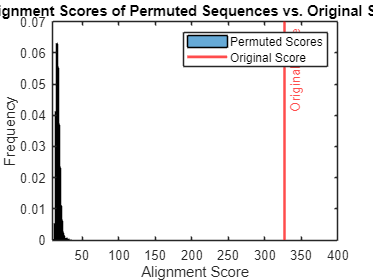


num_permutations = 15000;
perm_scores = zeros(1, num_permutations);

for i = 1:num_permutations

    permuted_sequence = sequenceBird(randperm(length(sequenceBird)));
    [score, ~] = swalign(sequenceRing, permuted_sequence);
    perm_scores(i) = score;
end


figure;
histogram(perm_scores, 'Normalization', 'probability');
hold on;


original_score = 327; % using the default scoring matrix
xline(original_score, 'r', 'LineWidth', 2, 'Label', 'Original Score');

title('Alignment Scores of Permuted Sequences vs. Original Score');

xlabel('Alignment Score');

ylabel('Frequency');

legend('Permuted Scores', 'Original Score');

hold off;


p_value = sum(perm_scores >= original_score) / num_permutations;
fprintf('p-value: %.4f\n', p_value);

p-value: 0.0000


**Analysis:**

The histogram on the right depicts the distribution of alignment scores generated from the randomized (permuted) sequences. As shown, the vast majority of these scores lie within the **0 to 25 range**, significantly lower than the alignment score of the original sequences (**327**). This stark contrast suggests that such a high alignment score is extremely unlikely to occur by random chance.

The resulting p-value is effectively **0**, indicating that none of the random permutations produced a score equal to or higher than the original. This implies that the observed alignment score is statistically significant. Therefore, it’s highly probable that the similarity between the original sequences is not coincidental but instead reflects a genuine biological relationship, such as shared evolutionary origins or conserved functional motifs.**Additional Insight:**

- The shape of the histogram, with a heavy concentration of low scores, suggests that random alignments typically yield weak matches, reinforcing the distinctiveness of the original score.

- The clear separation between the original score and the random distribution indicates that the original sequences contain specific, conserved regions that align well, providing evidence of functional or structural similarity.

- This analysis demonstrates that the permutation test effectively validates the reliability of the observed alignment, strengthening the case for meaningful biological significance.